# Calculation of R - T Relationship of PT1000

clear
clc

## Task 1 – Basis Information

## Task 2 – Matlab Program for PT1000 function

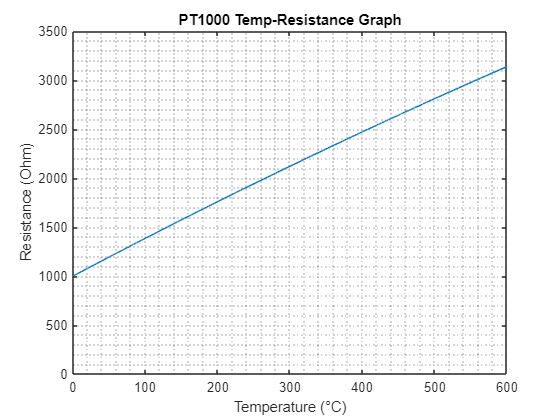

a = 3.9083e-3;
b = -0.5775e-6;
c = -4.183e-12;
R0 = 1e3;
temp_range = 0.1:0.1:600;

r_ptc = R0*(1 + a*temp_range + b*temp_range.^2);
plot(temp_range, r_ptc)
grid minor
xlim([0 600]); ylim([0 3500])
title('PT1000 Temp-Resistance Graph')
xlabel('Temperature (°C)'); ylabel('Resistance (Ohm)')

result = [temp_range' r_ptc'];

## Task 3 – Wheatstone Bridge

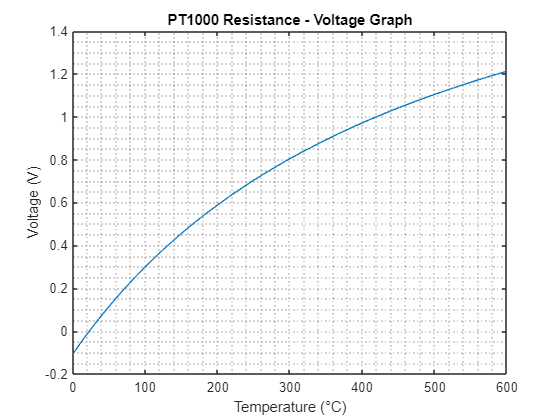

R1 = 1e3;
R4 = 1.088e3; R3 = R4; R2 = R3;
Vs = 5;
V0 = zeros(1, 6000);

for i=1:6000
    V0(i) = Vs*(r_ptc(i)/(r_ptc(i)+R2) - 0.5);
end

plot(temp_range, V0)
grid minor
title('PT1000 Resistance - Voltage Graph')
xlabel('Temperature (°C)'); ylabel('Voltage (V)')

result = [result V0'];

## Task 4 – Calculation of RTself

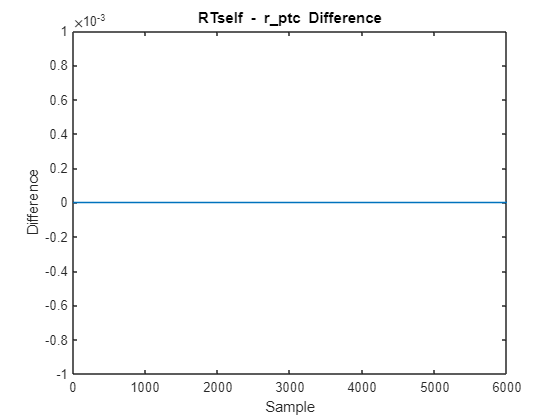

RTself = zeros(1, 6000);

for i = 1:6000
    RTself(i) = (V0(i)/Vs + 0.5) * (r_ptc(i) + R2);
end

plot(RTself - r_ptc)
title('RTself - r\_ptc Difference')
ylabel('Difference'); xlabel('Sample');
ylim([-1e-3 1e-3])

## Task 5 - Calculation of the temperature value

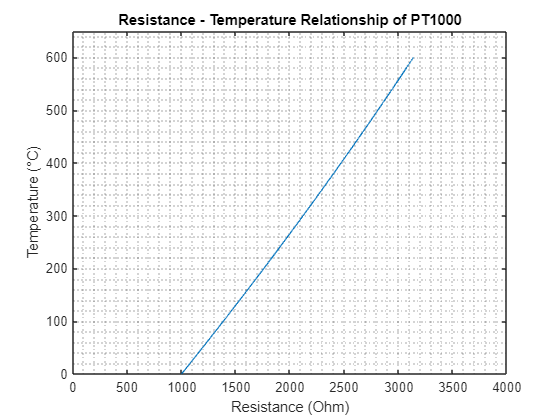

delta = a^2 - 4*b*(1 - r_ptc*1e-3);

% temp_vs_r_1 = (-a - sqrt(delta)) / (2*b); 
temp_vs_r_2 = (-a + sqrt(delta)) / (2*b);

% plot(temp_vs_r_1)
plot(r_ptc, temp_vs_r_2)
grid minor
xlim([0 4000]); ylim([0 650]);
xlabel('Resistance (Ohm)'); ylabel('Temperature (°C)');
title('Resistance - Temperature Relationship of PT1000');

## Task 6 - Tolerances

## Task 7 - Power Consumption

If all the resistors in the Wheatstone Bridge are 1088 Ohms, then the equivalent resistor of the circuit is

## 
$$\frac{1}{R_{\mathrm{eq}} }=\frac{1}{R_1 }+\frac{1}{R_2 }=\frac{1}{2*1088}+\frac{1}{2*1088}\Rightarrow R_{\mathrm{eq}} =1088\;\Omega$$


Req = 1088;

Then the current drawn is:

## 
$$\mathrm{Vs}=I*R_{\mathrm{eq}\;}$$


I = Vs/Req

I = 0.0046

And power consumption is:

## 
$$P=\frac{V^2 }{R_{\mathrm{eq}} }$$


P = Vs^2/Req

P = 0.0230